data_root_dir = '/home/linux-pc/gh/V1-Visual-Cortex-Visualization/data/crcns-pvc1/crcns-ringach-data/';
neuro_root_dir = 'neurodata/ac1/';
movie_root_dir = 'movie_frames/movie000_000.images/';
current_movie = "movie000_000_000.jpeg";
current_neuro_data = "ac1_u004_000.mat";

neuro_str = strcat(data_root_dir, neuro_root_dir, current_neuro_data);
load(neuro_str);

load_img = strcat(data_root_dir, movie_root_dir, current_movie);

%if ~strcmp(str1, str2)
%    disp('Strings are different');
%end

imread(load_img);

## Total Number of Conditions

pepANA.no_conditions

ans = 120

## Arrival Times for electrodes in pepANA.elec_list

pepANA.listOfResults{1}.repeat{1}.data{13}

ans = 1×2 cell array
    {[0.3537 0.4543 0.6036 0.6780 1.0123 1.1758 1.1779 1.1914 1.4126 1.4425 1.5338 1.6866 1.9662 2.5828 2.9451 3.3012 3.7744 3.9322 4.0201 4.6491 4.6791 4.7038 4.7153 4.7283 4.7530 4.9453 5.0114 5.0702 5.1571 5.2284 5.2450 5.2530 5.2793 5.3124 5.4489 5.4555 5.5446 5.6120 5.6444 5.9074 5.9447 6.0529 6.1861 6.4447 6.4658 6.4674 6.5947 6.6364 6.7368 6.7395 6.7992 7.1861 7.2076 7.2251 7.4116 7.4175 7.4342 7.4409 7.7366 7.7383 7.7427 7.7602 7.7752 7.9908 7.9988 8.0911 8.1284 8.2868 8.2950 8.3093 8.6980 8.7073 8.7739 8.9820 8.9861 9.3858 9.4068 9.4084 9.4132 9.4214 9.4284 9.4361 9.4736 9.4948 11.3779 11.5023 11.5521 11.5728 12.3103 12.4606 12.6606 12.7947 12.7983 12.9645 13.7019 13.7352 13.8687 14.5684 14.5775 14.6017 14.6351 14.6436 14.8638 14.8761 15.2851 15.3940 15.4686 15.4931 15.7483 16.3330 16.3440 16.8394 17.2726 17.2844 17.3010 17.4568 17.4682 17.5766 17.7683 18.4053 18.7387 19.0184 19.0555 19.1096 19.2100 19.6099 19.8890 19.8935 19.9430 19.9933 20.5885 22.0093 2

## Detected Waveforms at that time (48 samples of waveform snippets) (contains spikes and noise bc of low threshold) (1.6ms sampled at 30kHz at int8 precision)

pepANA.listOfResults{1}.repeat{1}.data{1}{2}

ans = 48×573 int8 matrix
     0    -6    -2     3    -3    -8     3     0    10    -7    -2     4    -6     3    -5     8    -8    -8    -3   -11     4   -15    -3    -8     9     2    -6    -4    -8    -1    -7     0    -9    10    -6     5    -7    -9    16    -3    20    -1   -11     9     0    -9    -3     5    -5   -16
    -1    -3    -2     2    -1     1    -3    -3    -2    -4    -3     7    -7     1    -7     5    -3    -9     1    -5     2   -18    -6   -16    -2     5   -10    -1    -7     3   -10    -1    -9     0     0     7   -13   -10     4    -7    17    -3   -17    -2     4   -14    -9     9    -8   -19
     3    -3    -2     1    -1     8    -3    -5    -8    -2     4     6    -6    -5    -7     2    -4     0     2    -1     1   -13    -4   -14    -7     4   -12    -8     1     3    -6    -5    -7    -7     2     5   -14    -5     3     5    18     2   -12    -7     7    -7   -12     4    -7   -11
     1    -3    -3     1    -3     6     1    -6    -2    -3     1     3

pepANA.listOfResults{1}.repeat{1}.data{1}{1}

ans =     0.4543    0.5465    0.8413    0.8919    1.0303    1.0468    1.0921    1.0955    1.0975    1.1127    1.1340    1.1364    1.1461    1.1505    1.1536    1.1659    1.1676    1.1728    1.1845    1.1907    1.1957    1.2081    1.2114    1.2207    1.2462    1.3205    1.7505    1.7624    2.0124    2.0194    2.6703    2.8907    2.9705    3.1544    3.2081    3.2501    3.8376    3.8666    3.8696    3.8726    3.8750    3.8808    3.8824    3.8884    3.8904    3.8929    3.8959    3.9338    3.9362    3.9381


% Length of each sample in ms
(size(pepANA.listOfResults{1}.repeat{1}.data{1}{2}', 2) / 30000) * 1000

ans = 1.6000

pepANA.listOfResults{1}.repeat{1}.data{1}{2}'

ans = 573×48 int8 matrix
     0    -1     3     1     1     2     0    -9   -19   -24   -16   -11   -17   -14    -9     1    -3    -7     0     2    -1    -3     0     9     9     5     4     1    -6    -7    -4    -3    -8    -9     1     0    -5     0     3     1     3     8     5     4     7    13    15     7
    -6    -3    -3    -3    -4    -8   -14   -15   -19   -26   -14    -4    -2    -1    -2    -3    -2    -3    -7    -9    -7    -4    -2     2     0    -1    -8    -6     3     5     8     6     9     7     1    -7    -6     1    -2    -3     1     4     0    -5    -2     3     1    -5
    -2    -2    -2    -3    -2    -1    -1   -12   -22   -23   -14     1    -3    -7    -8   -12   -14   -12    -6     2    -4    -7   -10    -6    -4     1     3     8     1     0     4    -2     1     5     5     3    -1    -4    -5     3     0    -4    -6    -9   -12    -6    -3    -3
     3     2     1     1     2     3    -6   -12   -16   -23   -18   -13   -11    -7     0     0     1     3

pepANA.listOfResults{1}.repeat{1}.data{1}{1}

ans =     0.4543    0.5465    0.8413    0.8919    1.0303    1.0468    1.0921    1.0955    1.0975    1.1127    1.1340    1.1364    1.1461    1.1505    1.1536    1.1659    1.1676    1.1728    1.1845    1.1907    1.1957    1.2081    1.2114    1.2207    1.2462    1.3205    1.7505    1.7624    2.0124    2.0194    2.6703    2.8907    2.9705    3.1544    3.2081    3.2501    3.8376    3.8666    3.8696    3.8726    3.8750    3.8808    3.8824    3.8884    3.8904    3.8929    3.8959    3.9338    3.9362    3.9381


## Electrodes

pepANA.elec_list

q = 573×48 int8 matrix
     0    -1     3     1     1     2     0    -9   -19   -24   -16   -11   -17   -14    -9     1    -3    -7     0     2    -1    -3     0     9     9     5     4     1    -6    -7    -4    -3    -8    -9     1     0    -5     0     3     1     3     8     5     4     7    13    15     7
    -6    -3    -3    -3    -4    -8   -14   -15   -19   -26   -14    -4    -2    -1    -2    -3    -2    -3    -7    -9    -7    -4    -2     2     0    -1    -8    -6     3     5     8     6     9     7     1    -7    -6     1    -2    -3     1     4     0    -5    -2     3     1    -5
    -2    -2    -2    -3    -2    -1    -1   -12   -22   -23   -14     1    -3    -7    -8   -12   -14   -12    -6     2    -4    -7   -10    -6    -4     1     3     8     1     0     4    -2     1     5     5     3    -1    -4    -5     3     0    -4    -6    -9   -12    -6    -3    -3
     3     2     1     1     2     3    -6   -12   -16   -23   -18   -13   -11    -7     0     0     1     3  

## Examining Waveforms

q = pepANA.listOfResults{1}.repeat{1}.data{1}{2}'

ans =      1    48


size(q(1, :))
one_waveform = q(1, :);

size(q)

ans =    573    48




fig0 = figure("Name", "Waveform")

fig0 =   Figure (49: Waveform) with properties:

      Number: 49
        Name: 'Waveform'
       Color: [0.9608 0.9608 0.9608]
    Position: [936 268 560 337.5000]
       Units: 'pixels'

  Show all properties


ax_0 = axes("Parent", fig0)

ax_0 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


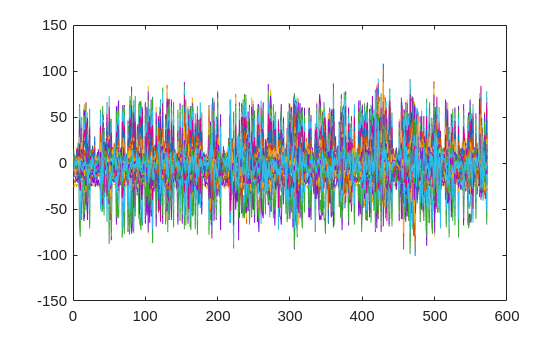

plot(ax_0, q)

% fig_multiple_spikes_electrode13 = figure("Name", "Channel 13 Electrode");
% ax_multi_spikes_channel13 = axes("Parent", fig_multiple_spikes_electrode13);
% plot(ax_multi_spikes_channel13, q);

## SVD of Waveforms

function mean_detected_signal = analyzeWaveform(condition, electrode, verbose)

condition = 1

    if nargin < 3

electrode = 1

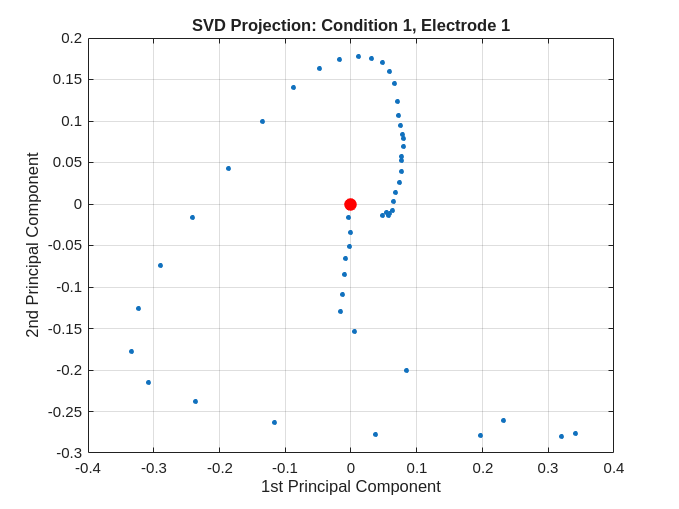

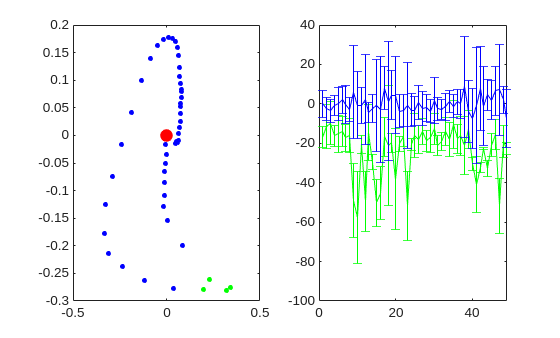

        verbose = false;

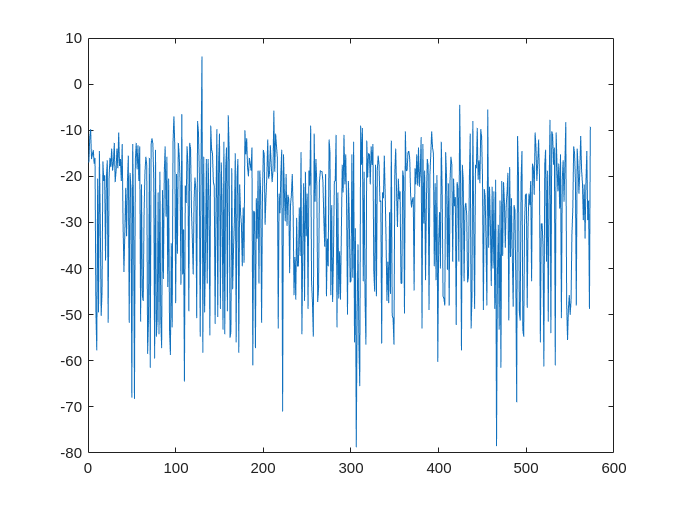

    end    

    % Check if pepANA is in workspace
    if ~evalin('base', 'exist(''pepANA'', ''var'')')
        error('pepANA structure not found in the base workspace.');

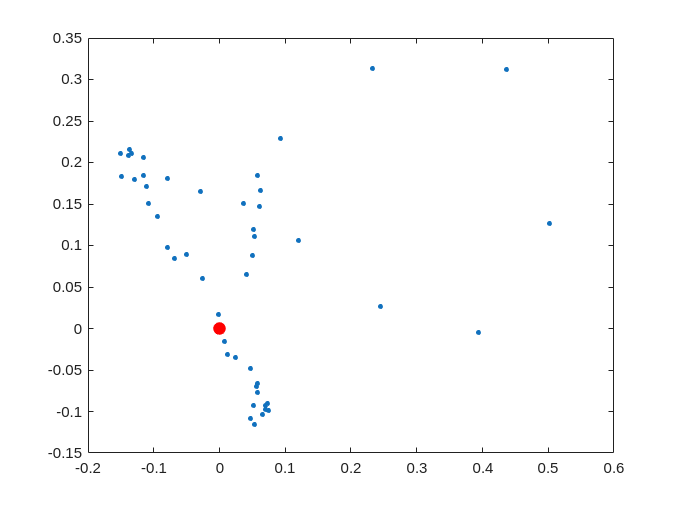

    end

    % Get waveform from pepANA in base workspace
    pepANA = evalin('base', 'pepANA');
    
    % Extract waveform
    waveform = pepANA.listOfResults{condition}.repeat{1}.data{electrode}{2};

    % Ensure waveform is in double precision
    waveform = double(waveform);

    % Perform SVD
    [~, ~, v] = svd(waveform);

    % Plot first two principal components
    if verbose
        fig1 = figure('Name', 'Original Waveforms', 'Position', [100, 100, 800, 600]);
        ax1 = axes('Parent', fig1);
        plot(ax1, v(:, 1), v(:, 2), '.', 'MarkerSize', 10);
        hold(ax1, 'on');
        plot(ax1, 0, 0, 'r.', 'MarkerSize', 25);
        xlabel(ax1, '1st Principal Component');

        ylabel(ax1, '2nd Principal Component');
        title(ax1, sprintf('SVD Projection: Condition %d, Electrode %d', condition, electrode));
        grid(ax1, 'on');
    end
        

    idx = kmeans(double(waveform'),2); %% cluster waveforms in 2 classes using k-means
    idx1 = find(idx==1); 
    idx2 = find(idx==2);

    % Determine which cluster is likely the signal
    mean1 = mean(waveform(:, idx1), 2);
    mean2 = mean(waveform(:, idx2), 2);

    total_amplitude1 = sum(abs(mean1));

ax3_2 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.1100 0.3347 0.8150]
            Units: 'normalized'

  Show all properties


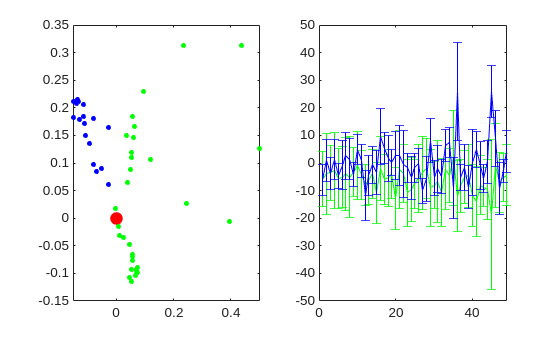

    total_amplitude2 = sum(abs(mean2));

    if total_amplitude1 > total_amplitude2
        signal_idx = idx1;
        noise_idx = idx2;

    else
        signal_idx = idx2;
        noise_idx = idx1;
    end

    if verbose
        fig2 = figure("Name", "SVD of Waveforms and Plot of a Waveform");
        ax3_1 = subplot(1, 2, 1, "Parent", fig2);
        plot(ax3_1, v(noise_idx, 1), v(noise_idx, 2), 'b.', 'markersize',10); 
        hold on;
        plot(ax3_1, 0, 0, 'r.', 'markersize', 25); 
        plot(ax3_1, v(signal_idx, 1), v(signal_idx, 2), 'g.', 'markersize', 10);
    
        ax3_2 = subplot(1, 2, 2, "Parent", fig2);
        errorbar(ax3_2, 1:size(waveform,1), mean(double(waveform(:, signal_idx)'),1), std(double(waveform(:, signal_idx)'),[],1), 'g'); 
        hold on;
        errorbar(ax3_2, 1:size(waveform,1), mean(double(waveform(:, noise_idx)'),1), std(double(waveform(:, noise_idx)'),[],1), 'b');
    
        xlim([0 49])
    end
    mean_detected_signal = mean(double(waveform(:, signal_idx)'),1);
end

data_root_dir = '/home/linux-pc/gh/V1-Visual-Cortex-Visualization/data/crcns-pvc1/crcns-ringach-data/';
neuro_root_dir = 'neurodata/ac1/';
movie_root_dir = 'movie_frames/movie000_000.images/';

condition = 26

current_movie = "movie000_000_000.jpeg";

electrode = 2

current_neuro_data = "ac1_u004_000.mat";

neuro_str = strcat(data_root_dir, neuro_root_dir, current_neuro_data);

spk =     0.0015    0.0176    0.0515    0.0845    0.1937    0.2264    0.2345    0.2758    0.3011    0.3184    0.3221    0.3269    0.3503    0.3672    0.4714    0.5394    0.5593    0.5718    0.5757    0.5932    0.5993    0.6024    0.6062    0.6093    0.6148    0.6215    0.6261    0.6299    0.6325    0.6357    0.6377    0.6413    0.6454    0.6512    0.6531    0.6584    0.6601    0.6625    0.6651    0.6670    0.6718    0.6735    0.6759    0.6784    0.6825    0.6850    0.6885    0.6927    0.6946    0.6987


load(neuro_str);

% Verifying the time between the samples varies
% time_stamp = pepANA.listOfResults{1}.repeat{1}.data{1}

latency = 0

ans = 'frame: 0'

ans = 'movie_image_string: movie001_006_000.jpeg'

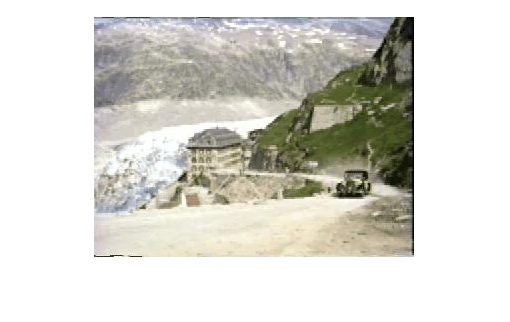

stimulus_image = 240×320×3 uint8 array
stimulus_image(:,:,1) =

   130   133   134   134   132   130   130   131    54    54    53    52    51    51    52    54    54    43    55    66   115   128   142   132   143   139   133   129   129   129   128   128    58    57    56    56    57    57    55    54    55    58    52    65    67    57    61    53    55    52    59    61    53    55    61    58   142   135   141   130   144   132   136   127   129   131   134   134   135   137   142   145   137   132   129   130   135   140   141   139   137   142   141   147   163   163   153   151   133   129   126   126   130   132   132   131   129   125   130   129   145   150   129   131    59    61    61    58    55    56    57    58    57    54    53    78   119   135   121   110   124   118   127   115   129   120   133   130   136   133   132   135   134   127   121   119   123   117   137   116   124   118   126   134   137   142   150   157   161   163   163   163   174   170   165   164

% time_stamp{1}(1) - time_stamp{1}(2)
% time_stamp{1}(2) - time_stamp{1}(3)

## Collecting all filtered data for machine learning purposes

All_Filtered_Data = struct('condition_id', {}, "waveform_timestamps", {}, "electrodes", {}, "stimulus_img", {});

% condition = 1
% electrode = 1
% signal = analyzeWaveform(condition, electrode, true);
% 
% % Plotting the detected spike waveform only
% fig0 = figure('Name', 'Detected Waveform', 'Position', [100, 100, 800, 600]);
% ax0 = axes('Parent', fig0);
% plot(ax0, signal)

filtered_signals = struct('electrode', {}, "signal", {})
condition = 1

for electrode = 1:16
    signal = analyzeWaveform(condition, electrode);
    filtered_signals(electrode).electrode = electrode;
    filtered_signals(electrode).signal = signal;
end


filtered_signals

## Indicating the noise and signal based on the first two dimensions

% waveform = pepANA.listOfResults{condition}.repeat{1}.data{electrode}{2};
% 
% [u, s, v] = svd(double(q));
% fig1 = figure('Name', 'Original Waveforms', "Position", [100, 100, 800, 600]);
% ax1 = axes("Parent", fig1);
% plot(ax1, v(:, 1), v(:, 2), '.', 'markersize', 10);
% hold on;
% plot(ax1, 0,0, 'r.', 'markersize', 25);

## Classifying Waveforms with K-means clustering

% fig2 = figure("Name", "SVD of Waveforms and Plot of a Waveform");
% 
% idx = kmeans(double(q'),2); %% cluster waveforms in 2 classes using k-means
% idx1 = find(idx==1); 
% idx2 = find(idx==2);
% 
% ax3_1 = subplot(1, 2, 1, "Parent", fig2);
% plot(ax3_1, v(idx1, 1), v(idx1, 2), 'b.', 'markersize',10); 
% hold on;
% plot(ax3_1, 0, 0, 'r.', 'markersize', 25); 
% plot(ax3_1, v(idx2, 1), v(idx2, 2), 'g.', 'markersize', 10);
% 
% ax3_2 = subplot(1, 2, 2, "Parent", fig2)
% errorbar(ax3_2, 1:size(q,1), mean(double(q(:, idx2)'),1), std(double(q(:, idx2)'),[],1), 'g'); 
% hold on;
% errorbar(ax3_2, 1:size(q,1), mean(double(q(:, idx1)'),1), std(double(q(:, idx1)'),[],1), 'b');
% 
% xlim([0 49])

% set(gcf, 'Renderer', 'painters'); % or 'opengl'

% waveform = pepANA.listOfResults{1}.repeat{1}.data{13}{2}(1, :)
% fig0 = figure("Name", "Single Waveform");
% ax0 = axes("Parent", fig0);
% plot(ax0, waveform);

% plot(ax0, pepANA.listOfResults{1}.repeat{1}.data{13}{1})

## Natural image sequences data:

% Indices of the movie frame that appeared 60ms before a spike 
c = 1 % condition
T = 3/90 % 3 frames (of the same image) at 90 Hz of the monitor (duration of each frame in seconds.)
spk = pepANA.listOfResults{c}.repeat{1}.data{13}{1};
spk = spk - 60e-3; % frames 60 ms before a spike sample
frame_idx = floor(spk/T);
frame_idx

frame_idx(1);
n_prefix_frame_zeros = 3 - (floor(log10(frame_idx(1))) + 1)

## Getting the frames

function stimulus_image = identify_stimulus_image(condition, electrode, latency, verbose)

    if nargin < 4
        verbose = false;
    end

    if nargin < 3
        latency = 60e-3;
        verbose = false;
    end

    % Check if pepANA is in workspace
    if ~evalin('base', 'exist(''pepANA'', ''var'')')
        error('pepANA structure not found in the base workspace.');
    end

    % Get waveform from pepANA in base workspace
    pepANA = evalin('base', 'pepANA');
    
    data_root_dir = '/home/linux-pc/gh/V1-Visual-Cortex-Visualization/data/crcns-pvc1/crcns-ringach-data/';

    movie_id = pepANA.listOfResults{condition}.values(1);
    segment_id = pepANA.listOfResults{condition}.values(2);

    if segment_id{1} > 0
        n_prefix_zeros = 3 - (floor(log10(segment_id{1})) + 1);
        if n_prefix_zeros > 1
            prefix_zeros_segment_id = sprintf('%s', repmat("0", 1, n_prefix_zeros));
        else
            prefix_zeros_segment_id = "0";
        end
    else
        prefix_zeros_segment_id = "00";
    end

    % Indices of the movie frame that appeared 60ms before a spike 
    % c = 1 % condition
    T = 3/90; % 3 frames (of the same image) at 90 Hz of the monitor (duration of each frame in seconds.)
    % electrode = 1
    spk = pepANA.listOfResults{condition}.repeat{1}.data{electrode}{1};
    spk = spk - latency; % frames of latency value (default is 60 ms) before a spike sample
    frame_idx = floor(spk/T);

    % Create the string to show the image that is the stimulus to the detected spike
    if verbose
        sprintf('frame: %d', frame_idx(1))
    end
    if frame_idx(1) > 0
        n_prefix_frame_zeros = 3 - (floor(log10(frame_idx(1))) + 1);
        if n_prefix_frame_zeros > 1
            prefix_zeros_frame_idx = sprintf('%s', repmat("0", 1, n_prefix_frame_zeros));
        else
            prefix_zeros_frame_idx = "0";
        end
    else 
        prefix_zeros_frame_idx = "00";
    end

    movie_image_string = "movie00" + int2str(movie_id{1}) + "_" + prefix_zeros_segment_id + int2str(segment_id{1}) + "_" + prefix_zeros_frame_idx + int2str(frame_idx(1)) + ".jpeg";
    movie_image_dir = data_root_dir + "movie_frames/" + "movie00" + int2str(movie_id{1}) + "_" + prefix_zeros_segment_id + int2str(segment_id{1}) + ".images/";

    if verbose
        sprintf('movie_image_string: %s', movie_image_string)
    end

    image_path = strcat(movie_image_dir, movie_image_string);
    stimulus_image = imread(image_path);

    if verbose
        fig_img = figure("Name", "Stimulus Image");
        ax_img = axes("Parent", fig_img);
        imshow(stimulus_image,"Parent", ax_img)
    end
end

condition = 26
electrode = 2

spk = pepANA.listOfResults{condition}.repeat{1}.data{electrode}{1};
spk

% latency = 60e-3
latency = 0

stimulus_image = identify_stimulus_image(condition, electrode, latency, true)








